# Formatif

## Question 7

Num = [0 1.5 28.5 202.8 652.2 740.4];
Den = [1 23 210 950 2044 1632];

G_s = tf(Num, Den);
[b, a] = tfdata(G_s, 'v');
[R, P, K] = residue(b, a)

R =    0.1000 + 0.0000i
   0.2000 + 0.1000i
   0.2000 - 0.1000i
   0.6000 + 0.0000i
   0.4000 + 0.0000i


P =   -8.0000 + 0.0000i
  -5.0000 + 3.0000i
  -5.0000 - 3.0000i
  -3.0000 + 0.0000i
  -2.0000 + 0.0000i



K =

     []




%Trouver le poids
poids = abs(R)./abs(real(P))

poids =     0.0125
    0.0447
    0.0447
    0.2000
    0.2000



%Toute les fonctions
sys1 = tf([R(4)],[1 -P(4)]);
sys2 = tf([R(5)],[1 -P(5)]);

%Fonctions mit ensemble
G2_s = sys1 + sys2

G2_s =
 
     s + 2.4
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties


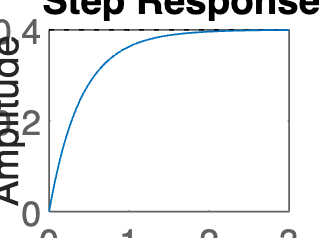


%Montrer les echelons
step(G2_s)

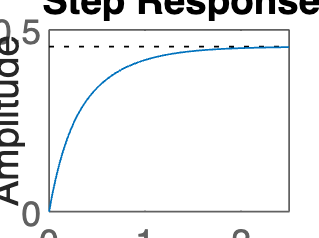

figure
step(G_s)

## Question 8

clc
clear all
close all

load("/Users/francoisdesautels/Documents/GitHub/S5_APP3/DonneesIdentifMasseRessortAmorti.mat")

dt = t(2);
Diff1 = diff(x)./dt;
Diff2 = diff(Diff1)./dt;

Y = x(1:end-2)

Y =          0
    0.0000
    0.0001
    0.0002
    0.0004
    0.0006
    0.0009
    0.0012
    0.0016
    0.0020


X = [Fext(1:end-2) Diff1(1:end-1) Diff2]

X =    50.0000    0.0250   49.7976
   50.0000    0.0748   49.5913
   50.0000    0.1244   49.3809
   50.0000    0.1737   49.1665
   50.0000    0.2229   48.9479
   50.0000    0.2719   48.7254
   50.0000    0.3206   48.4989
   50.0000    0.3691   48.2685
   50.0000    0.4173   48.0341
   50.0000    0.4654   47.7959



A = pinv(X)*Y

A =     0.0100
   -0.0410
   -0.0100



k = 1/A(1)

k = 100.0000

b = -k*A(2)

b = 4.1000

m = -k*A(3)

m = 1.0020


G = tf([(1/m)], [1 (b/m) (k/m)])

G =
 
         0.998
  --------------------
  s^2 + 4.092 s + 99.8
 
Continuous-time transfer function.
Model Properties



[y2, t2] = lsim(G, Fext, t)

y2 =     0.0000
    0.0000
    0.0001
    0.0002
    0.0004
    0.0006
    0.0009
    0.0012
    0.0016
    0.0020


t2 =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090


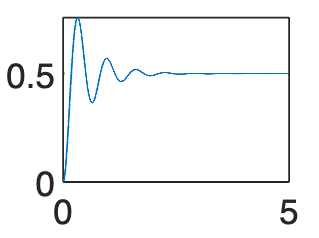


plot(t2, y2)


erreur = y2 - x

erreur =     0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


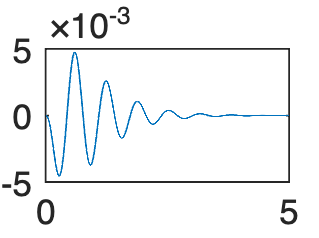


plot(t, erreur)

## Question 9

clc
close all
clear all

load("/Users/francoisdesautels/Documents/GitHub/S5_APP3/DonneesIdentifMasseRessortAmorti.mat")

A = [0 1;
     -100 -4];
B = [0;
     1];
C = [1 0];
D = [0];

sys = ss(A, B, C, D)

sys =
 
  A = 
         x1    x2
   x1     0     1
   x2  -100    -4
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Pro

figure
impulse(sys)
